%     采样频率   2000MHz
%%%%    信噪比范围  -10：2：10
%%%    载频   [Fs/10, Fs/4]=[200MHz 500MHz]
%      带宽   [Fs/40, Fs/16]=[50MHz 125MHz]
%      信号点数     [512, 1920]


addpath('f\','f\yuan\');
rng default         %用默认种子，matlab刚开始默认就是0
x=1*11;  %信号个数
[wav, mod] = gaiGenerateRadarWaveforms(x);



parentDir = '123';%获取操作系统的文件路径，将其赋值给 parentDir 变量
dataDir = 'STFT';%定义了一个名为 dataDir 的变量，用于存放生成的数据文件。这里将其设置为 TFDDatabase
% 有STFT,CWT,WVD
squGenerateTFDfiles(parentDir,dataDir,wav,mod,2000e6)
                                                % parentDir：时频分析图数据文件的保存路径。
                                                % dataDir：生成的数据文件所在的目录名称。
                                                % wav：生成时频分析图的波形。
                                                % mod：波形的调制类型。
                                                % 2000e6：信号的采样率。

folders = fullfile(parentDir,dataDir,{'RECT','LFM','NLFM','BPSK','QPSK','BFSK','QFSK'});
%创建一个包含三个字符串的元胞数组，每个字符串都是一个文件夹名，代表了数据集中的三个不同类别。



%加载数据
imds = imageDatastore(folders, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 
[imdsTrain,imdsTest,imdsValidation] = splitEachLabel(imds,0.8,0.1);
%每个标签的训练数据占 80%，测试数据占 10%，验证数据占 10%



%加载预训练网络
net = squeezenet;
inputSize = net.Layers(1).InputSize;


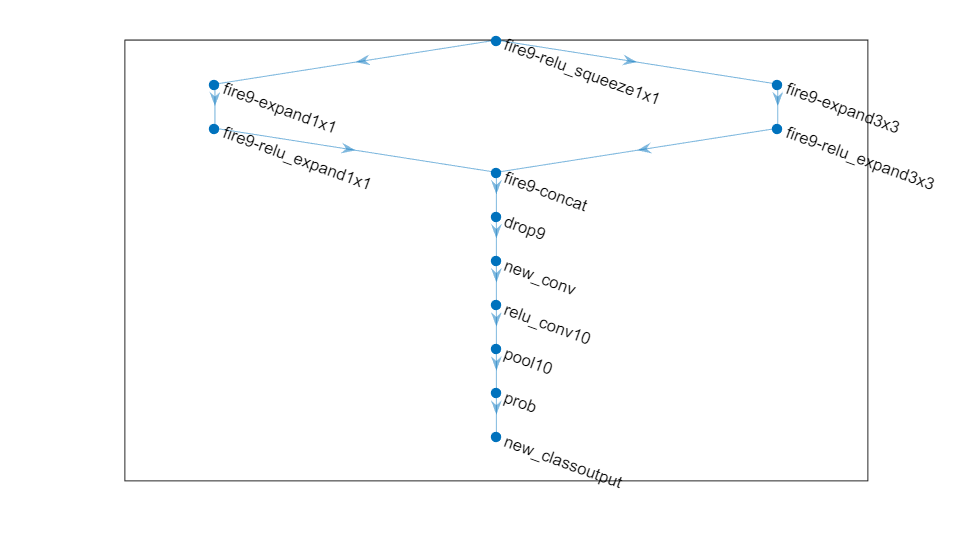


%替换最终层
lgraph = layerGraph(net);
[learnableLayer,classLayer] = findLayersToReplace(lgraph);

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])


%冻结初始层
layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);



%网络设置
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

%---设置参数---
miniBatchSize = 33;%每一轮进的张数
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...%轮数
    'InitialLearnRate',3e-4, ...%学习率
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'ExecutionEnvironment','gpu',...
    'Plots','training-progress');


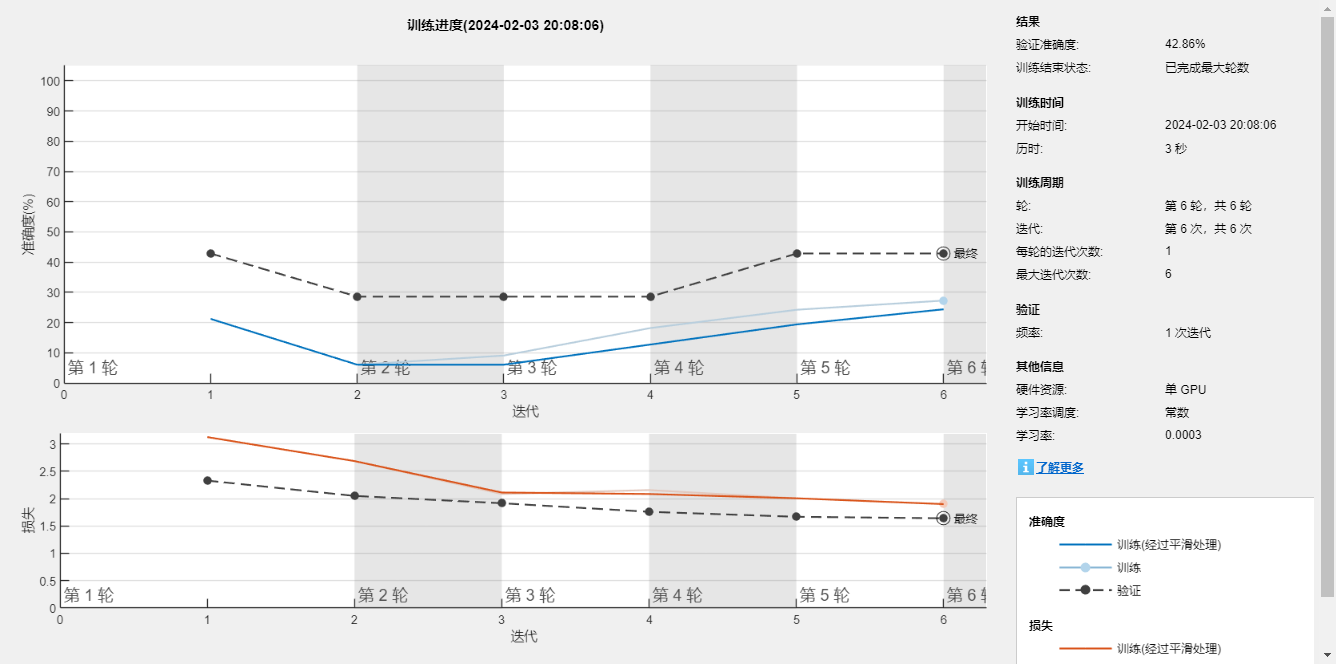


%---开始训练---
[trainedNet,outdata] = trainNetwork(augimdsTrain,lgraph,options);

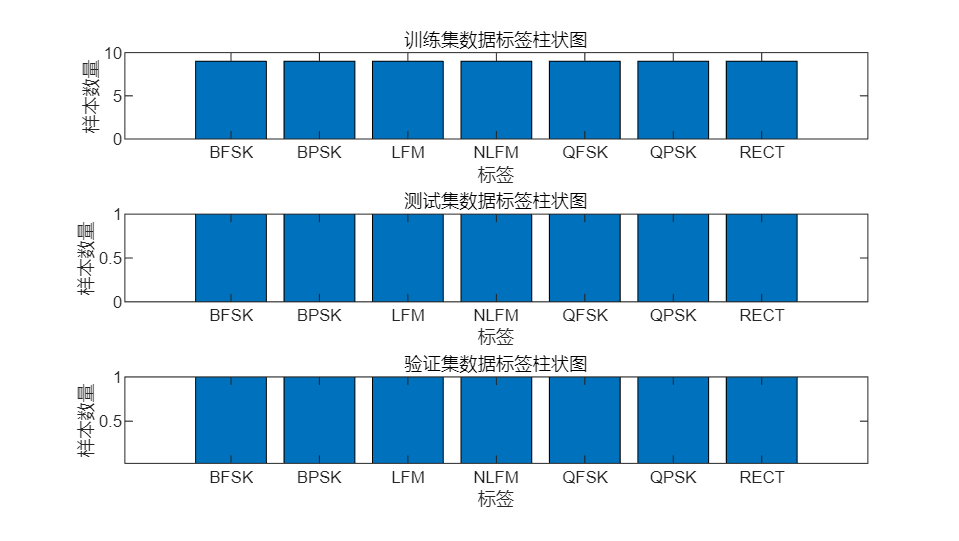


%%%%%%%%%%%%%%%    数据集分布图   %%%%%%%%%%%%%%%%%%%

% 统计每个标签在训练集中的样本数量
trainLabelCount = countEachLabel(imdsTrain);
% 统计每个标签在测试集中的样本数量
testLabelCount = countEachLabel(imdsTest);
% 统计每个标签在验证集中的样本数量
validationLabelCount = countEachLabel(imdsValidation);
% 提取标签和对应的样本数量
labels = trainLabelCount.Label;
trainCounts = trainLabelCount.Count;
testCounts = testLabelCount.Count;
validationCounts = validationLabelCount.Count;
% 绘制训练集柱状图
subplot(3, 1, 1);
bar(trainCounts)
xlabel('标签')
ylabel('样本数量')
title('训练集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)
% 绘制测试集柱状图
subplot(3, 1, 2);
bar(testCounts)
xlabel('标签')
ylabel('样本数量')
title('测试集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)
% 绘制验证集柱状图
subplot(3, 1, 3);
bar(validationCounts)
xlabel('标签')
ylabel('样本数量')
title('验证集数据标签柱状图')
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels)

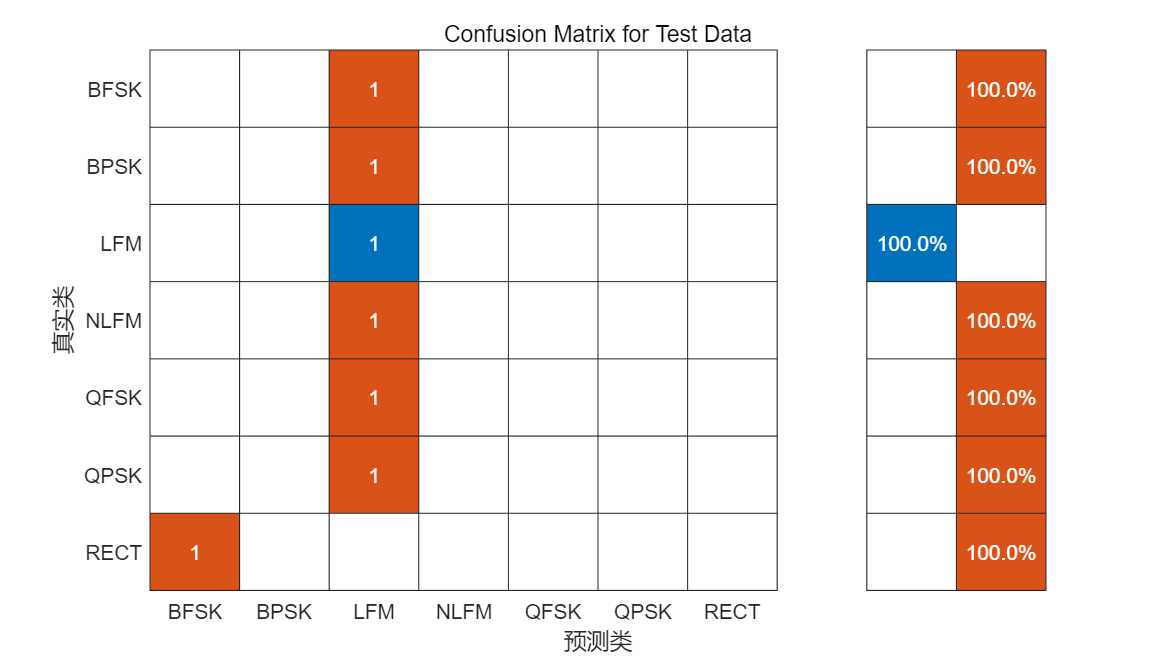

%%%%%%%%%%%%%%%%%%%输出混淆图并保存网络%%%%%%%%%%%%%%%
predicted = classify(trainedNet,imdsTest);
% figure;
% confusionchart(predicted,imdsTest.Labels,'Normalization','column-normalized')


figure
cm = confusionchart(imdsTest.Labels,predicted);
cm.Title = 'Confusion Matrix for Test Data';
cm.RowSummary = 'row-normalized';
cm.Parent.Position = [cm.Parent.Position(1:2) 740 424];


%保存网络
save('net\shendunet','trainedNet','outdata');
